fc = 18e3;           % 载波频率，主要用于纠正采样频偏（SFO），在发射端可忽略
sf = 7;              % 扩频因子
bw = 2e3;            % 带宽 2kHz
fs = 48e3;           % 采样率 48kHz
Nchirp = 2^sf/bw*fs; %一个Chirp的采样点数

phy = LoRaPHY(fc, sf, bw, fs);
phy.has_header = 0;         % explicit header 模式
phy.cr = 1;                 % code rate = 4/8 (1:4/5 2:4/6 3:4/7 4:4/8)
phy.crc = 0;                % 允许 payload CRC
phy.preamble_len = 8;       % 前导码： 8 basic upchirps


% 编码3个6
symbols = phy.encode([1, 9, 2, 10, 1, 6, 8, 10, 0, 10, 1]')

symbols =     45
    85
    85
    41
    93
    73
    25
   113
    89
    73


sig = phy.modulate(symbols)

preamble =    1.0000 + 0.0000i
   0.9915 - 0.1305i
   0.9660 - 0.2587i
   0.9240 - 0.3823i
   0.8664 - 0.4994i
   0.7940 - 0.6079i
   0.7082 - 0.7060i
   0.6104 - 0.7921i
   0.5024 - 0.8647i
   0.3859 - 0.9226i


netid =    1.0000 + 0.0000i
   0.9967 - 0.0817i
   0.9867 - 0.1627i
   0.9701 - 0.2426i
   0.9471 - 0.3208i
   0.9179 - 0.3968i
   0.8826 - 0.4700i
   0.8416 - 0.5401i
   0.7950 - 0.6066i
   0.7433 - 0.6690i


sfd =    1.0000 + 0.0000i
   0.9915 + 0.1305i
   0.9660 + 0.2587i
   0.9240 + 0.3823i
   0.8664 + 0.4994i
   0.7940 + 0.6079i
   0.7082 + 0.7060i
   0.6104 + 0.7921i
   0.5024 + 0.8647i
   0.3859 + 0.9226i


data =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


sig =    1.0000 + 0.0000i
   0.9915 - 0.1305i
   0.9660 - 0.2587i
   0.9240 - 0.3823i
   0.8664 - 0.4994i
   0.7940 - 0.6079i
   0.7082 - 0.7060i
   0.6104 - 0.7921i
   0.5024 - 0.8647i
   0.3859 - 0.9226i


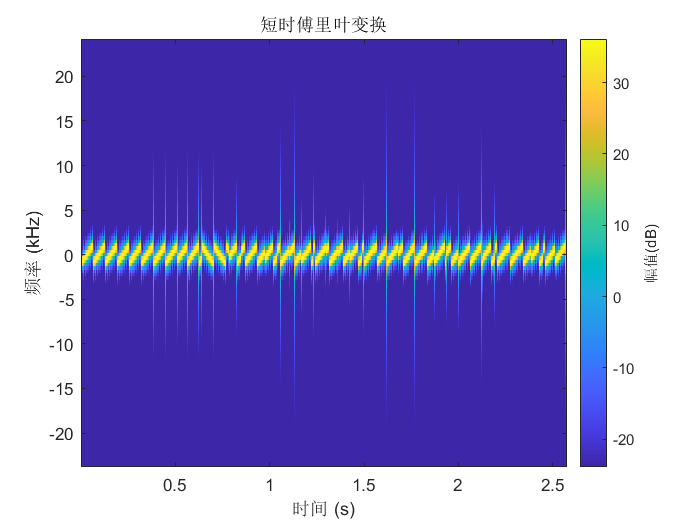

stft(sig, fs)


zs = zeros(1, Nchirp*5)

zs =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


chirp_sound = cat(1, zs', sig)     % 基带信号

chirp_sound =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


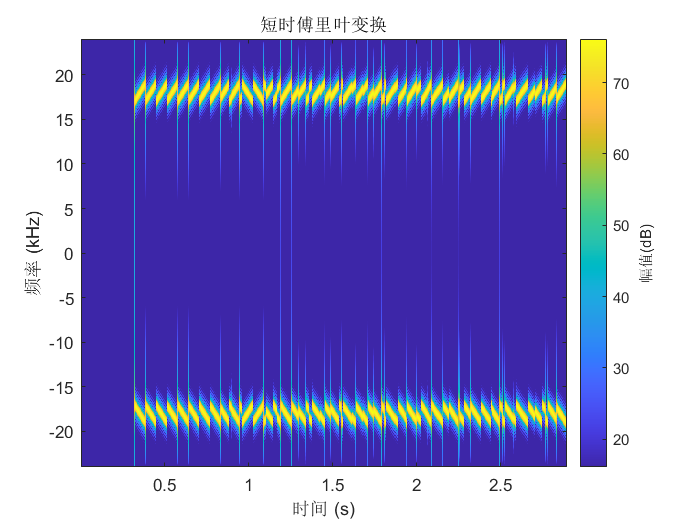


t = (0:length(chirp_sound)-1)/fs;

car_chirp_sound = real(chirp_sound).*cos(2*pi*fc*t)'+imag(chirp_sound).*sin(-2*pi*fc*t)';
car_chirp_sound=car_chirp_sound*200;

stft(car_chirp_sound, fs, "FFTLength", 2048)

dlmwrite("send/chirp.txt", car_chirp_sound)



